# Introduction: System Analysis

Once appropriate mathematical models of a system have been obtained, either in differential equation or transfer function form, we may then analyze these models to predict how the system will respond in both the time and frequency domains. To put this in context, control systems are often designed to improve stability, speed of response, steady-state error, or prevent oscillations. In this section, we will show how to determine these dynamic properties from the system models.

Key MATLAB commands used in this tutorial are: [`lsim`](https://www.mathworks.com/help/control/ref/lsim.html) , [`tf`](http://www.mathworks.com/help/toolbox/control/ref/tf.html) ,  [`ssdata`](http://www.mathworks.com/help/toolbox/control/ref/ssdata.html) ,  [`pole`](http://www.mathworks.com/help/toolbox/control/ref/pole.html) ,  [`eig`](http://www.mathworks.com/help/techdoc/ref/eig.html) ,  [`step`](http://www.mathworks.com/help/toolbox/control/ref/step.html) ,  [`pzmap`](http://www.mathworks.com/help/toolbox/control/ref/pzmap.html) ,  [`bode`](http://www.mathworks.com/help/ident/ref/bode.html) ,  [`linearSystemAnalyzer`](http://www.mathworks.com/help/control/ref/linearsystemanalyzer-app.html)

## Time Response Overview

**Time response** represents how the state of a dynamic system changes in time when subjected to a particular input and initial condition. Since dynamic models consist of differential equations, some integration must be performed in order to determine the time response of the system. For some simple systems, a closed-form analytical solution may be available. For most systems though, especially nonlinear systems or those subject to complicated inputs, this integration must be carried out numerically. Fortunately, MATLAB provides many useful resources for calculating time responses for many types of inputs, as we shall see in the following sections.

A nice property of linear dynamic systems is that their time response consists of the sum of the system's response to its initial conditions and its response to its input. These solutions to the governing differential equations are referred to as the homogeneous and particular solutions, respectively.

### **Free (Natural) Response**

The following script allows you to choose between two example systems with initial condition (`x0`) and no forcing input (`u = 0`). The chosen system's free response is simulated for 100 seconds using the `lsim` function and the resulting output, `y`, is then plotted versus time. The two choices are a **1st-order** system and a **2nd-order** system. The meaning of these two classes of system are explained later in this page. Notice that both systems are "stable" and decay to an equilibrium, but one free response oscillates while the other does not. The details of how to predict the character of a system's natural response is also explained later in this page. 

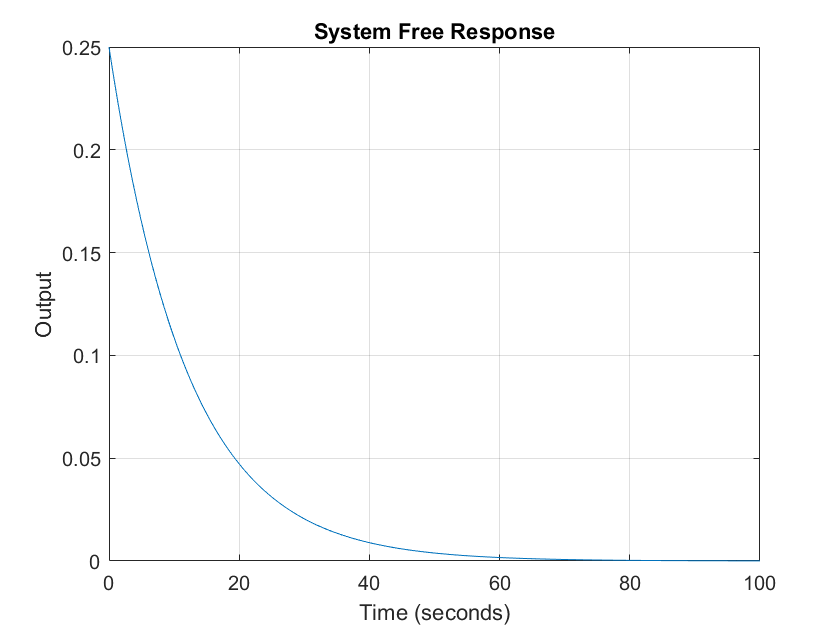

[A B C D] = tf2ss([3],[12 1]); x0 = 1;
sys = ss(A,B,C,D);
t = 0:0.1:100; 
u = 0*t;
[y] = lsim(sys,u,t,x0);
figure(1);
plot(t,y);
grid
xlabel('Time (seconds)')
ylabel('Output')
title('System Free Response')

### **Forced Response**

In the following script you can then add a forcing input to the system you chose above. Specifically, you will observe the response of the system to one of three inputs, as well as to the initial conditions previously provided. The **Step** is a constant input that steps at time t = 0 and remains at the value for the remaining time. The **Ramp** is a linear input that increases at a constant slope. While the **Sine** is a sinusoidal input with frequency equal to 1 rad/sec. Examine some of the different responses and consider what determines the resulting shape.

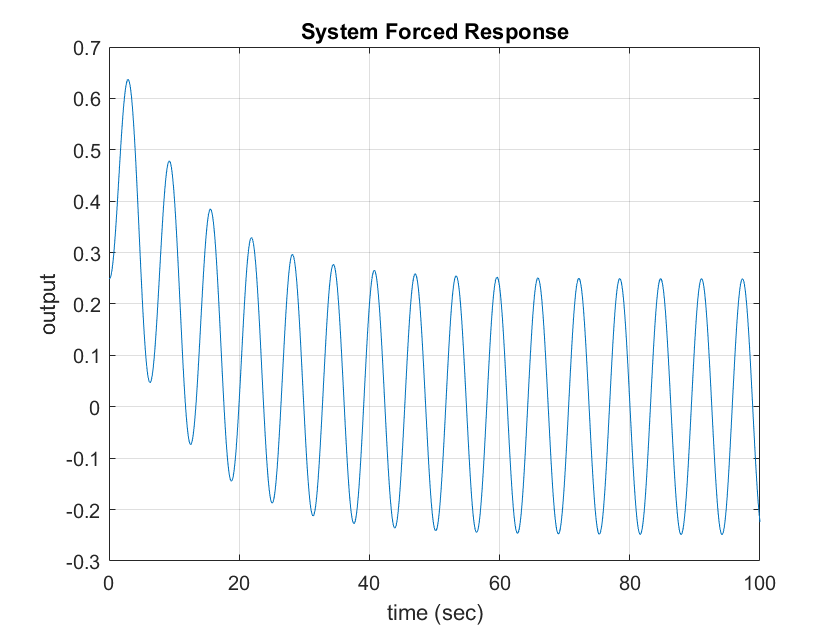

u = sin(t);
y = lsim(sys,u,t,x0);
plot(t,y);
grid
xlabel('time (sec)')
ylabel('output')
title('System Forced Response')

What you should observe is the property mentioned previously where the system's free response is added to (or subtracted from) its particular solution, which has the same form as the forcing input (though possibly scaled and/or shifted). For stable systems, you will generally observe a **transient** period until the free response dies out, after which the **steady-state **response of the system remains. A special example of this behavior which is of particular interest is when the input is a sinusoid. A system's response to sinusoidal inputs forms the basis of frequency response analysis.

## Frequency Response Overview

Most of the examples presented in this tutorial are modeled by linear, constant-coefficient differential equations and are thus linear time-invariant (LTI). LTI systems have the extremely important property that if the input to the system is a sinusoid, then the steady-state output will also be a sinusoid of the same frequency, but, in general, with different magnitude and phase. These magnitude and phase differences change with frequency and comprise the **frequency response** of the system.

The frequency response of a system can be found by feeding the system sinusoidal inputs of different frequencies and then observing the resulting change in amplitude and phase of the output in steady-state. Consider the following example where the frequency `w` of a sine input can be varied and the resulting response is plotted after the transient dies out (after 50 seconds).

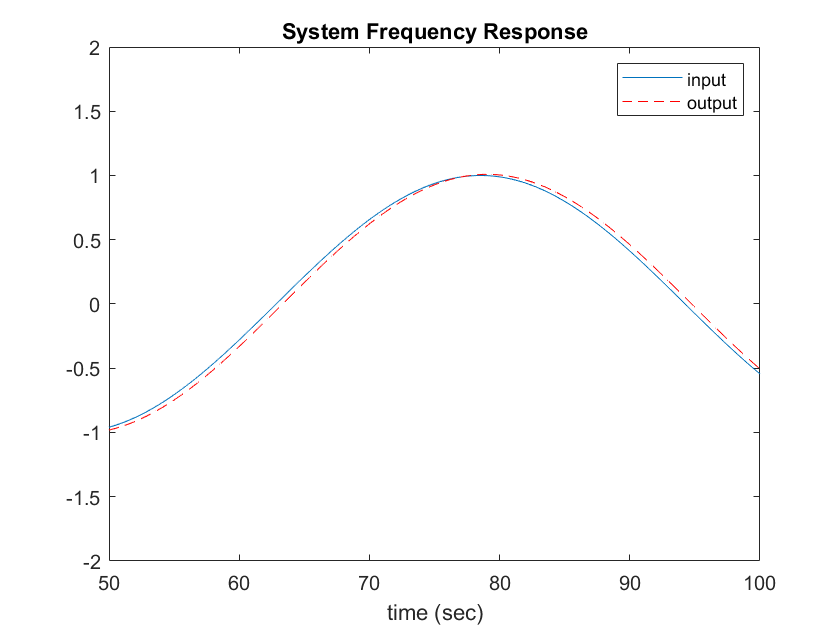

s = tf('s');
G = 1/(s^2 + 0.5*s + 1);
w =0.1;
t = 0:0.1:100;
u = sin(w*t);
[y,t] = lsim(G,u,t);
figure(2);
plot(t,u,t,y,'r--')
legend('input','output')
xlabel('time (sec)')
title('System Frequency Response')
axis([50 100 -2 2])

Alternatively, the frequency response of a system can be found from its transfer function in the following manner: create a vector of frequencies (varying between zero or "DC" to infinity) and compute the value of the plant transfer function at those frequencies. If $G(s)$ is the open-loop transfer function of a system and $\omega$ is the frequency vector, we then plot $G(j\omega)$ versus $\omega$. Since $G(j\omega)$ is a complex number, we can plot both its magnitude and phase (the **Bode Plot**) or its position in the complex plane (the **Nyquist Diagram**). Both methods display the same information, but in different ways.

## Stability

For our purposes, we will use the **Bounded Input Bounded Output (BIBO)** definition of stability which states that a system is stable if the output remains bounded for all bounded (finite) inputs. Practically, this means that the system will not "blow up" while in operation.

The transfer function representation is especially useful when analyzing system stability. If all poles of the transfer function (values of $s$ for which the denominator equals zero) have negative real parts, then the system is stable. If any pole has a positive real part, then the system is unstable. If we view the poles on the complex s-plane, then all poles must be in the left-half plane (LHP) to ensure stability. If any pair of poles is on the imaginary axis, then the system is marginally stable and the system will oscillate indefinitely. A system with purely imaginary poles is not considered BIBO stable. For such a system there will exist finite inputs that lead to an unbounded response, for example, if an input excites a natural resonance. The poles of an LTI system model can easily be found in MATLAB using the `pole` command, an example of which is shown below: 

s = tf('s');
G = 1/(s^2+2*s+5)

G =
 
        1
  -------------
  s^2 + 2 s + 5
 
Continuous-time transfer function.



pole(G)

ans =   -1.0000 + 2.0000i
  -1.0000 - 2.0000i


This system is stable since the real parts of the poles are both negative. More specifically, the real part of the poles determines the rate of decay (if negative) or growth (if positive) of the system's natural response. The imaginary part of a system's poles determines the frequency of oscillation of its natural response. If the poles are purely real, then the system's natural response does not oscillate. For this example, the system's free response decays at rate of $e^{-t}$ and oscillates with a frequency of 2 rad/sec. 

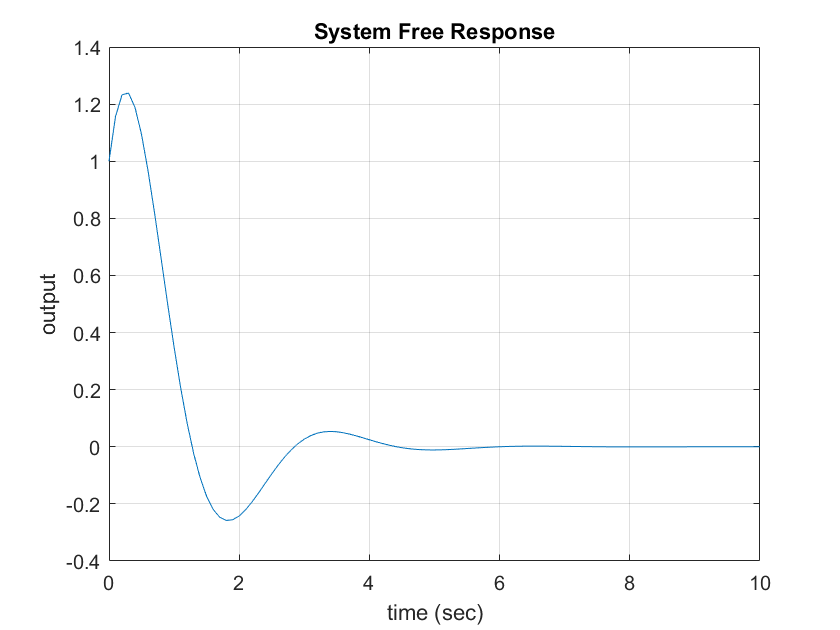

[A,B,C,D] = ssdata(G);
sys = ss(A,B,C,D);
x0 = [1;1];
t = 0:0.1:10; 
u = 0*t;
[y] = lsim(sys,u,t,x0);
figure(3);
plot(t,y);
grid
xlabel('time (sec)')
ylabel('output')
title('System Free Response')

The stability of a system may also be found from the state-space representation. In fact, the poles of the transfer function are the eigenvalues of the system matrix $A$. We can use the `eig` command to calculate the eigenvalues using either the LTI system model directly, `eig(G)`, or the system matrix as shown below.

eig(A)

ans =   -1.0000 + 2.0000i
  -1.0000 - 2.0000i


## System Order

The order of a dynamic system is the order of the highest derivative of its governing differential equation. Equivalently, it is the highest power of $s$ in the denominator of its transfer function. The important properties of first-, second-, and higher-order systems will be reviewed in this section.

### First-Order Systems

First-order systems are the simplest dynamic systems to analyze. Some common examples include mass-damper systems and RC circuits. The general form of the first-order differential equation is as shown in the following.


$$ 
\dot{y} + a y = b u \quad \textrm{or} \ \quad \tau \dot{y} + y = k_{dc} u
$$


The form of a first-order transfer function is


$$ 
G(s) = \frac{b}{s+a} \quad \textrm{or} \ \quad G(s) =  \frac{k_{dc}}{\tau s + 1}$$


where the parameters $k_{dc}$ and $\tau$ completely define the character of the first-order system.

**DC Gain**

The DC gain, $k_{dc}$, is the ratio of the magnitude of the steady-state step response to the magnitude of the step input. For stable transfer functions, the **Final Value Theorem** demonstrates that the DC gain is the value of the transfer function evaluated at $s$ = 0. For first-order systems of the forms shown, the DC gain is $k_{dc} = b/a$. 

**Time Constant**

The time constant of a first-order system is $T_c = \tau = 1/a$ which is equal to the time it takes for the system's response to reach 63% of its steady-state value for a step input (from zero initial conditions) or to decrease to 37% of the initial value for a system's free response. More generally, it represents the time scale for which the dynamics of the system are significant. 

**Poles/Zeros**

First-order systems have a single real pole, in this case at $s = -a$. Therefore, the system is stable if $a$ is positive and unstable if $a$ is negative. Standard first-order system have no zeros. 

**Step Response**

We can calculate the system time response to a step input of magnitude $u$ using the following MATLAB commands:

k_dc = 5;
Tc = 10;
u = 2;

s = tf('s');
sys = k_dc/(Tc*s+1)

sys =
 
     5
  --------
  10 s + 1
 
Continuous-time transfer function.



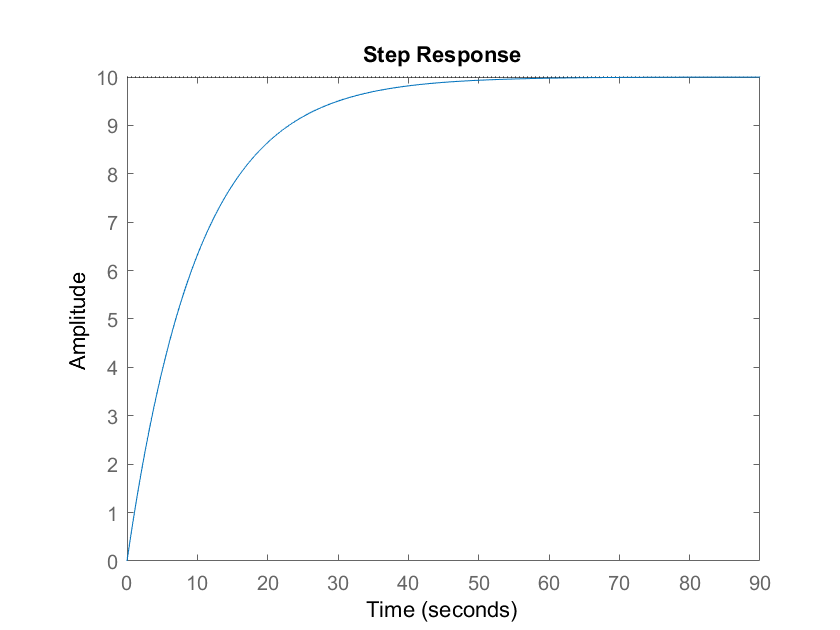

step(u*sys)

Note: MATLAB also provides a powerful graphical user interface for analyzing LTI systems which can be accessed using the syntax `linearSystemAnalyzer('step',G)`.

If you right-click on the step response graph and select **Characteristics**, you can choose to have several system metrics overlaid on the response: peak response, settling time, rise time, and steady-state value.

**Settling Time**

The settling time, $T_s$, is the time required for the system output to fall within a certain percentage (i.e. 2%) of the steady-state value for a step input. The settling times for a first-order system for the most common tolerances are provided below. Note that the tighter the tolerance, the longer the system response takes to settle to within this band, as expected.

- 10% settling time, $
T_{s} = \frac{2.3}{a} = 2.3\tau
$

- 5% settling time, $
T_{s} = \frac{3.0}{a} = 3.0\tau
$

- 2% settling time, $
T_{s} = \frac{3.9}{a} = 3.9\tau
$

- 1% settling time, $
T_{s} = \frac{4.6}{a} = 4.6\tau
$

**Rise Time**

The rise time, $T_r$, is the time required for the system output to rise from some lower level x% to some higher level y% of the final steady-state value. For first-order systems, the typical range is 10% - 90%.

**Bode Plots**

Bode diagrams show the magnitude and phase of a system's frequency response, $G(j\omega)$, plotted with respect to frequency $\omega$. We can generate the Bode plot of a system $G$ in MATLAB using the syntax `bode(G)` as shown below. 

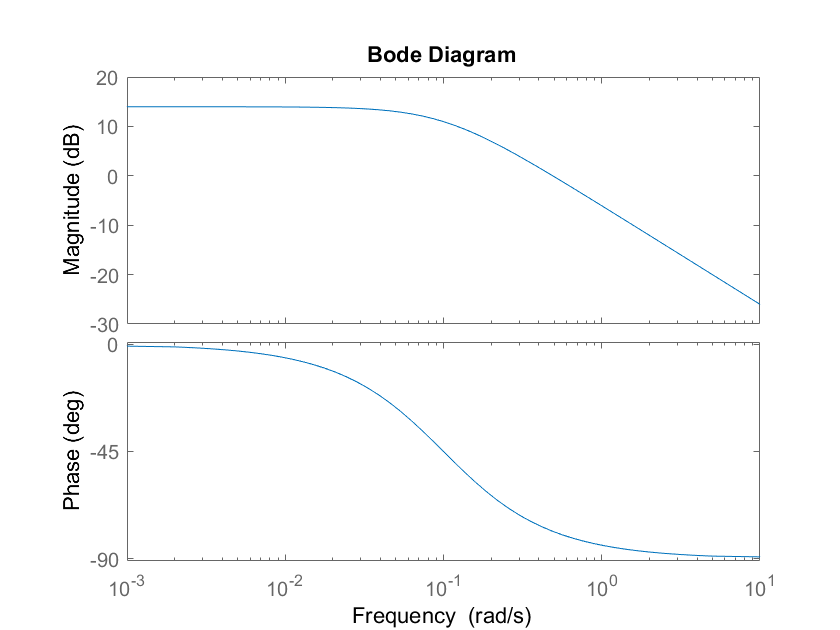

bode(sys)

Again the same results could be obtained using the Linear System Analyzer GUI, `linearSystemAnalyzer('bode',G)`.

Bode plots employ a logarithmic frequency scale so that a larger range of frequencies are visible. Also, the magnitude is represented using the logarithmic **decibel unit (dB)** defined as:


$$
M_{dB} = 20 \log_{10} (M)
$$


As with the frequency axis, the decibel scale allows us to view a much larger range of magnitudes on a single plot. Also, as we shall see in subsequent tutorials, when components and controllers are placed in series, the transfer function of the overall system is the product of the individual transfer functions. Using the dB scale, the magnitude plot of the overall system is simply the sum of the magnitude plots of the individual transfer functions. The phase plot of the overall system is also just the sum of the individual phase plots.

The low frequency magnitude of the first-order Bode plot is $20\log(k_{dc})$. The magnitude plot has a bend at the frequency equal to the absolute value of the pole (ie. $\omega = a$), and then decreases 20 dB for every factor of ten increase in frequency (slope = -20 dB/decade). The phase plot is asymptotic to 0 degrees at low frequencies, and asymptotic to -90 degrees at high frequencies. Between frequency 0.1a and 10a, the phase changes by approximately -45 degrees for every factor of ten increase in frequency (-45 degrees/decade).

We will see in the Frequency Methods for Controller Design Section how to use Bode plots to calculate closed-loop stability and performance of feedback systems.

### Second-Order Systems

Second-order systems are also commonly encountered in practice, and are the simplest type of dynamic system to exhibit oscillations. Examples include mass-spring-damper systems and RLC circuits. In fact, many true higher-order systems may be approximated as second-order in order to facilitate analysis. 

The canonical form of the second-order differential equation is as shown in the following.


$$ 
m \ddot{y} + b \dot{y} + k y = f(t) \quad \textrm{or} \ \quad \ddot{y} + 2\zeta\omega_n \dot{y} + \omega_n^2 y = k_{dc} \omega_n^2 u
$$


The canonical second-order transfer function has the following form, in which it has two poles and no zeros.


$$ 
G(s) = \frac{1}{ms^2+bs+k}  \quad \textrm{or} \ \quad   G(s) = \frac{k_{dc} \omega_n^2}{s^2 + 2\zeta\omega_n s + \omega_n^2}
$$


The parameters $k_{dc}$, $\zeta$, and $\omega_n$ characterize the behavior of a canonical second-order system.

**DC Gain**

The DC gain, $k_{dc}$, again is the ratio of the magnitude of the steady-state step response to the magnitude of the step input, and for stable systems it is the value of the transfer function when $s = 0$. For the forms given,


$$
k_{dc} = \frac{1}{k}
$$


**Damping Ratio**

The damping ratio $\zeta$ is a dimensionless quantity charaterizing the rate at which an oscillation in the system's response decays due to effects such as viscous friction or electrical resistance. From the above definitions, 


$$
\zeta = \frac{b}{2 \sqrt{k m}}
$$


**Natural Frequency**

The natural frequency $\omega_n$ is the frequency (in rad/s) that the system will oscillate at when there is no damping, $\zeta = 0$. 


$$
\omega_n = \sqrt{\frac{k}{m}}
$$


**Poles/Zeros**

The canonical second-order transfer function has two poles at:


$$
s_p = -\zeta \omega_n \pm j \omega_n \sqrt{1-\zeta^2}
$$


**Underdamped Systems**

If $\zeta < 1$, then the system is **underdamped**. In this case, both poles are complex-valued with negative real parts; therefore, the system is stable but oscillates while approaching the steady-state value. Specifically, the natural response oscillates with the damped natural frequency, $\omega_d = \omega_n \sqrt{1-\zeta^2}$ (in rad/sec).

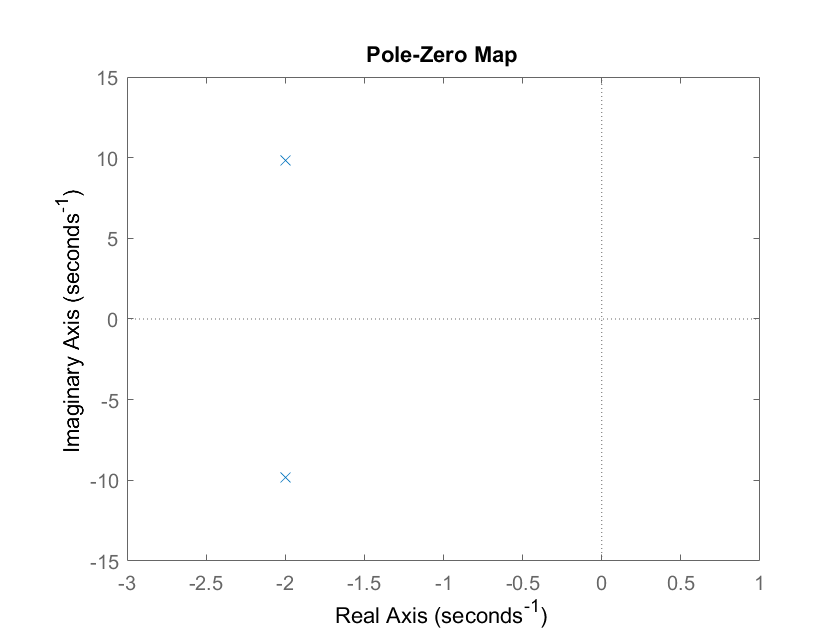

k_dc = 1;
w_n = 10;
zeta = 0.2;

s = tf('s');
G1 = k_dc*w_n^2/(s^2 + 2*zeta*w_n*s + w_n^2);
figure;
pzmap(G1)
axis([-3 1 -15 15])

**Settling Time**

The settling time, $T_s$, is the time required for the system ouput to fall within a certain percentage of the steady-state value for a step input. For a canonical second-order, underdamped system, the settling time can be approximated by the following equation: 


$$
T_s = \frac{- \ln(\mathrm{tolerance}\;\mathrm{fraction})}{\zeta \omega_n}
$$


The settling times for the most common tolerances are presented in the following:

- 10% settling time, $
T_{s} = \frac{2.3}{\zeta\omega_n} = \frac{2.3}{\sigma}
$

- 5% settling time, $
T_{s} = \frac{3.0}{\zeta\omega_n} = \frac{3.0}{\sigma}
$

- 2% settling time, $
T_{s} = \frac{3.9}{\zeta\omega_n} = \frac{3.9}{\sigma}
$

- 1% settling time, $
T_{s} = \frac{4.6}{\zeta\omega_n} = \frac{4.6}{\sigma}
$

Use the drop-down menu to view the settling time for different tolerances on the step response plot.

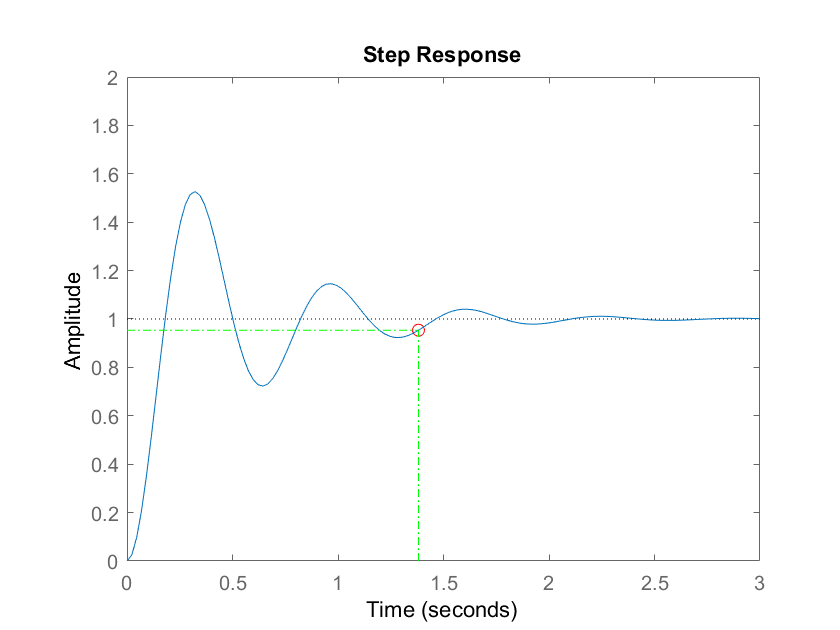

step(G1)
axis([0 3 0 2])
displaySettlingTime(G1,0.05)

**Percent Overshoot**

The percent overshoot is the percent by which a system's step response exceeds its final steady-state value. For a second-order underdamped system, the percent overshoot $Mp$ is directly related to the damping ratio by the following equation. Here, $Mp$ is a decimal number where 1 corresponds to 100% overshoot.


$$
Mp = e^{\left( \frac{-\zeta\pi}{\sqrt{1-\zeta^2}} \right)}
$$


For second-order underdamped systems, the 2% settling time, $T_s$, 10-90% rise time, $T_r$, and percent overshoot, $Mp$, are related to the damping ratio and natural frequency as shown below.


$$
T_s \approx \frac{4}{\zeta \omega_n}
$$



$$
T_r \approx \frac{1.8}{\omega_n}
$$



$$
\zeta = \frac{-\ln(Mp)}{\sqrt{\pi^2+\ln^2(Mp)}}
$$


**Pole Locations**

As the various parameters of a canonical second-order system are related to one another, it is often helpful to visualize the system's poles in the complex s-plane. Recall that underdamped canonical second-order systems have complex conjugate poles ($-\sigma \pm j\omega_d$) where $-\sigma$ is the real part of the poles and $\pm j\omega_d$ are the imaginary parts. If we imagine a right triangle with one leg being the real part of the pole and one leg being the imaginary part of the pole, the hypotenuse is the system's (undamped) natural frequency $\omega_n$. The angle the hypotenuse makes with the real axis is called $\beta$ and relates to the system's damping ratio $\zeta =\cos \left(\beta \right)$. In the following, interactive sliders allow you to explore how the moving the poles in the complex s-plane affects the parameters and the resulting unit step response.

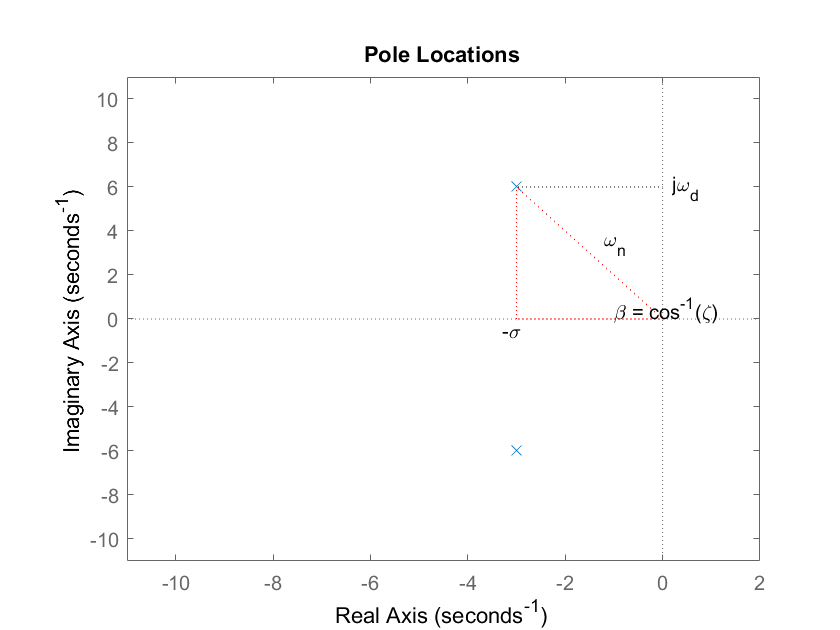

sigma =3;
wd =6;
wn = sqrt(sigma^2 + wd^2); % natural frequency
zeta = sigma/wn; % damping ratio
sys = tf([wn^2],[1 2*sigma wn^2]);
displayPoles(sys,zeta,wn);
title('Pole Locations')
axis([-11 2 -11 11])

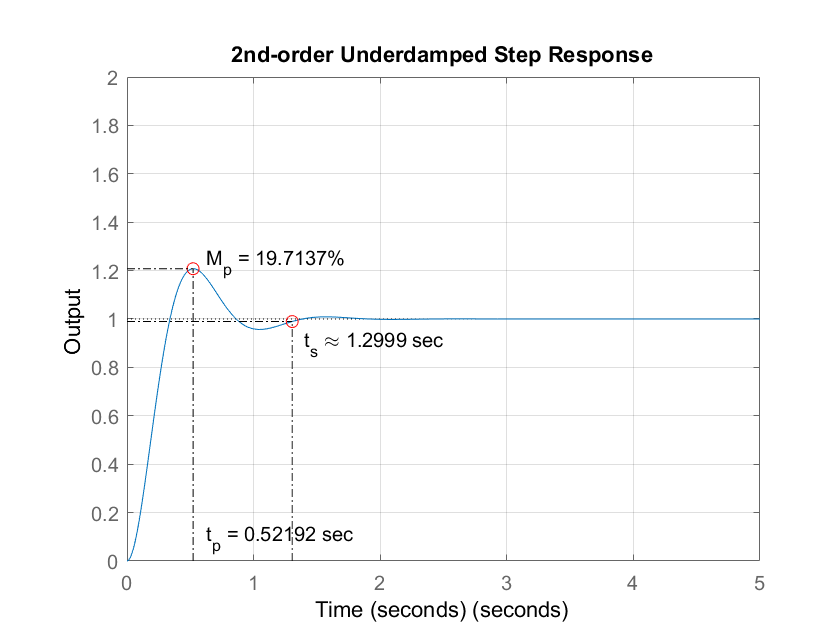

t = 0:0.01:5; 
step(sys,t)
axis([0 5 0 2])
grid
displayCharacteristics(sys,0.02);
xlabel('Time (seconds)')
ylabel('Output')
title('2nd-order Underdamped Step Response')

**Critically damped and Overdamped Systems**

If you increase $\zeta$ the poles of the second-order system eventually become real. This transition occurs at $\zeta = 1$ and at this point the system is **critically damped**. For critically damped systems both poles are real and equal, $s_p = -\zeta\omega_n$. For a canonical second-order system, the quickest settling time is achieved when the system is critically damped. If $\zeta > 1$, then the system is **overdamped**. In this case, both poles are real and negative; therefore, the system is stable and does not oscillate. In the following interactive script, you can use the slider to increase $\zeta$from the point of critical damping. As you increase $\zeta$you will notice how the two real poles of the system move. As the poles move farther apart, you should observe that the "slower" pole nearer to the origin will dominate the response.

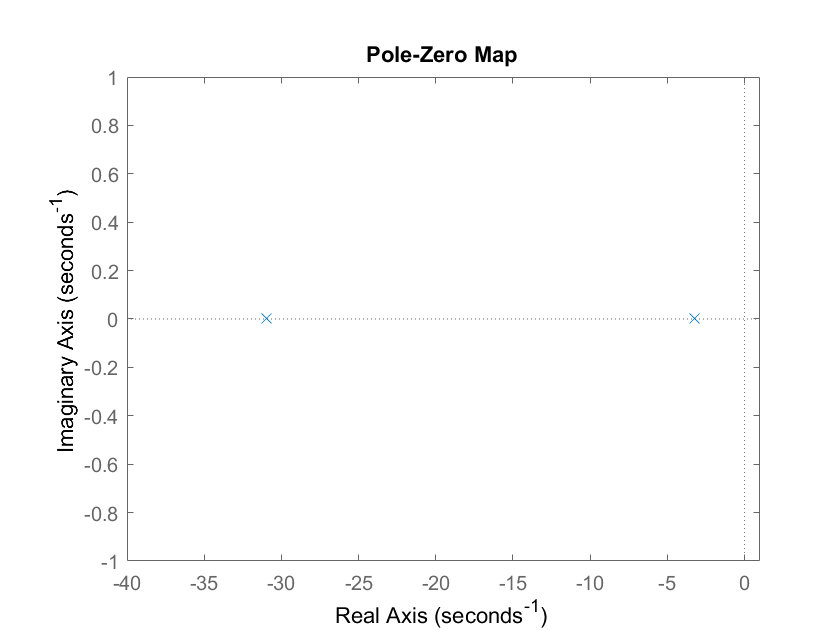

zeta =1.71;
G2 = k_dc*w_n^2/(s^2 + 2*zeta*w_n*s + w_n^2);

figure(5);
pzmap(G2)
axis([-40 1 -1 1])

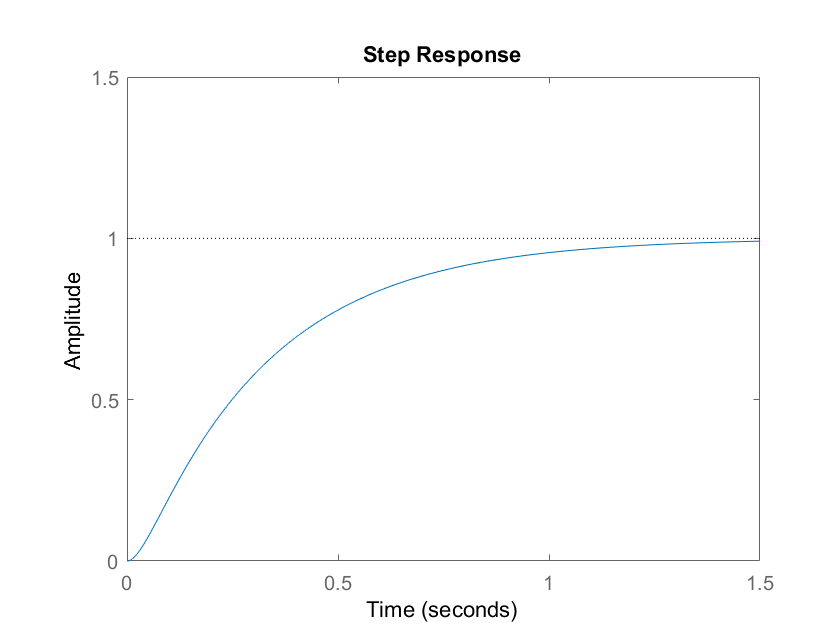

step(G2)
axis([0 1.5 0 1.5])

**Undamped Systems**

If $\zeta = 0$, then the system is **undamped**. In this case, the poles are purely imaginary $s_p = -\pm j\omega_n$; therefore, the system is marginally stable and the step response oscillates indefinitely. The frequency of the oscillation is equal to $\omega_n$ (which is also equal to $\omega_d$). In the following interactive script you can use the slider to vary the natural frequency and observe the effect on the system's poles and step response.

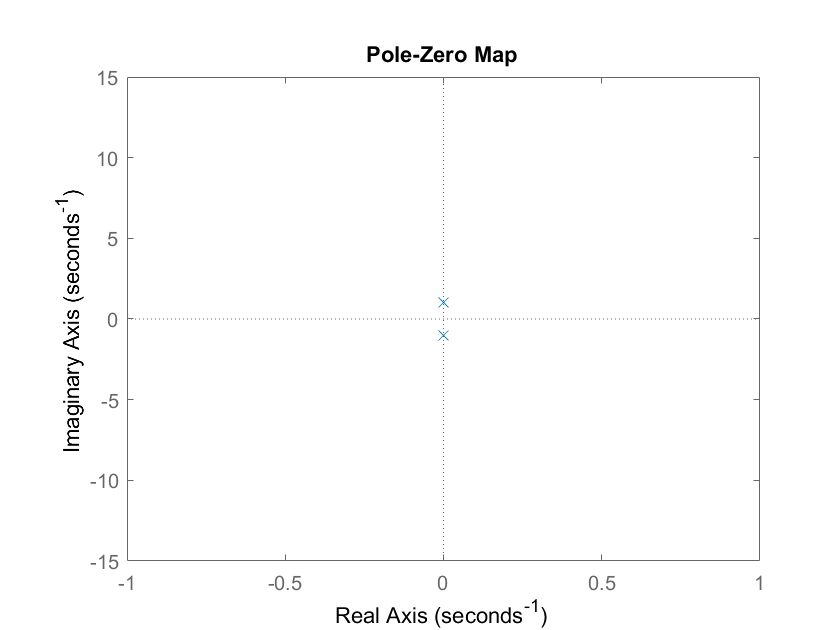

zeta = 0;
w_n = 1;
G4 = k_dc*w_n^2/(s^2 + 2*zeta*w_n*s + w_n^2);
figure(7)
pzmap(G4)
axis([-1 1 -15 15])

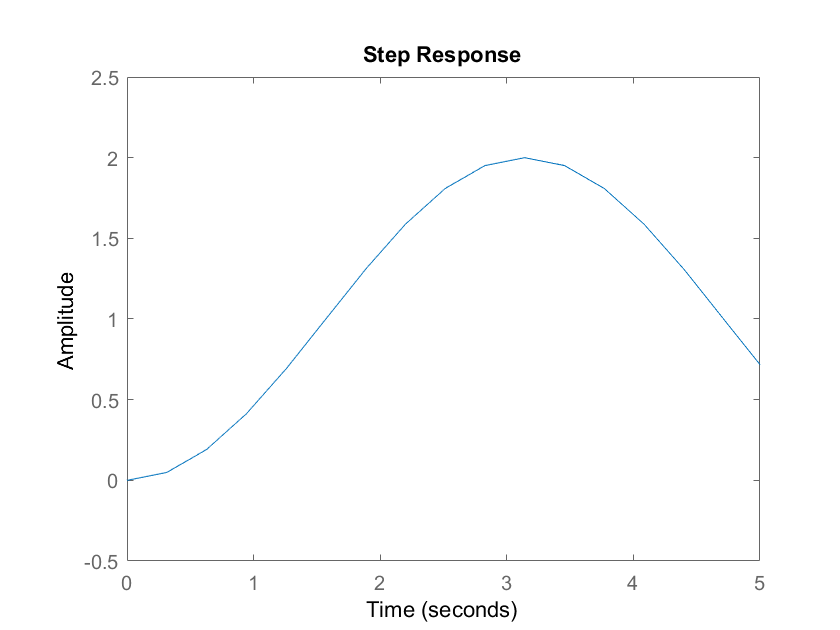

step(G4)
axis([0 5 -0.5 2.5])

**Bode Plot**

In the following, the slider can be used to vary the damping ratio $\zeta$ of a canonical second-order system and observe the resulting Bode magnitude and phase plots. By default, the plots for each chosen value of damping ratio will be shown on the same figure. If you press the "Reset figure" button, the Bode plot figure will be cleared.

 
 clear G5;

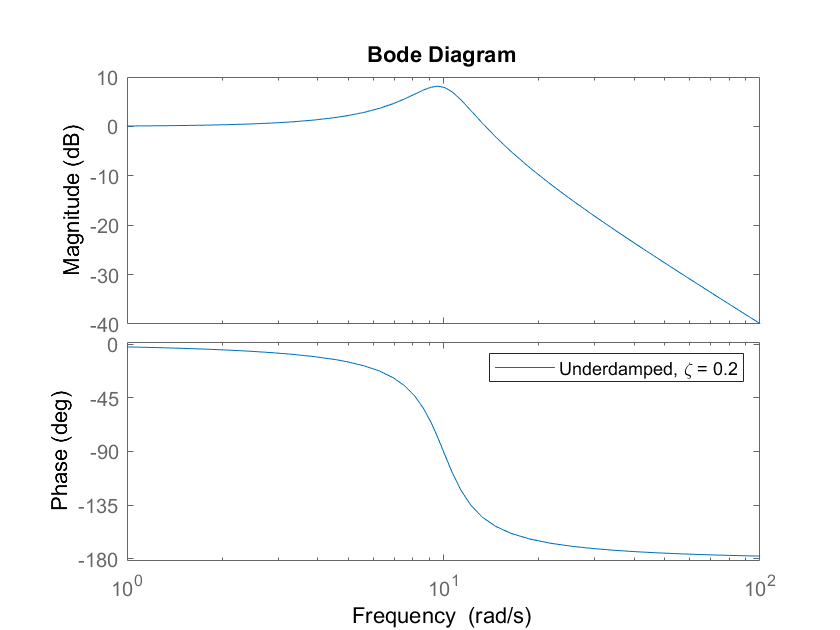

if ~exist('G5') 
     figure(8);clf;
     lgd = [];
end
zeta = 0.2;
k_dc = 1; w_n = 10; s = tf('s'); 
G5 = k_dc*w_n^2/(s^2 + 2*zeta*w_n*s + w_n^2);
figure(8);
hold on;
bode(G5)
if zeta == 0
    newlgd = "Undamped:, \zeta = " + num2str(zeta);
elseif zeta < 1
    newlgd = "Underdamped, \zeta = " + num2str(zeta);
elseif zeta == 1
    newlgd = "Critically damped, \zeta = " + num2str(zeta);
else
    newlgd = "Overdamped, \zeta = " + num2str(zeta);  
end

lgd = [lgd; newlgd];
legend(lgd)

The magnitude of the bode plot of a second-order system drops off at -40 dB per decade in the limit, while the relative phase changes from 0 to -180 degrees. For underdamped systems, we also see a resonant peak near the natural frequency, $\omega_n$ = 10 rad/s. The size and sharpness of the peak depends on the damping in the system, and is characterized by the quality factor, or **Q-Factor**, defined below. The Q-factor is an important property in signal processing.


$$
Q = \frac{1}{2\zeta}
$$


*The following function is used in the script above.*

function displaySettlingTime(sys, threshold) 
[y,t] = step(sys);
stepResults = stepinfo(y,t,'SettlingTimeThreshold',threshold);
indexSettling = find(t>=stepResults.SettlingTime,1);
hold on;
plot(t(indexSettling),y(indexSettling),'ro');
plot([0 t(indexSettling)],[y(indexSettling) y(indexSettling)],'g-.');
plot([t(indexSettling) t(indexSettling)],[0 y(indexSettling)],'g-.'); 
hold off;
end

function displayPoles(sys,zeta,wn) 
sigma = zeta*wn;
wd = wn*sqrt(1-zeta^2);
pzmap(sys)
hold on;
plot([0 -sigma], [0 wd],'r:');
text(-sigma/2+0.3,wd/2+0.5,['\omega_n']);
text(-sigma/3,0.5,['\beta = cos^{-1}(\zeta)']);
plot([-sigma -sigma], [0 wd],'r:');
text(-sigma-0.3,-0.5,['-\sigma']);
plot([0 -sigma], [wd wd],'k:');
plot([0 -sigma], [0 0],'r:');
text(0.2,wd,['j\omega_d']);
hold off;
end

function displayCharacteristics(sys,threshold) 
[y,t] = step(sys);
stepResults = stepinfo(y,t,'SettlingTimeThreshold',threshold);
indexSettling = find(t>=stepResults.SettlingTime,1);
hold on;
plot(t(indexSettling),y(indexSettling),'ro');
plot([0 t(indexSettling)],[y(indexSettling) y(indexSettling)],'k-.');
plot([t(indexSettling) t(indexSettling)],[0 y(indexSettling)],'k-.');
text(stepResults.SettlingTime+0.1,0.9,['t_s \approx ',num2str(stepResults.SettlingTime),' sec']);
plot(stepResults.PeakTime,stepResults.Peak,'ro');
plot([stepResults.PeakTime stepResults.PeakTime], [0 stepResults.Peak],'k-.');
plot([0 stepResults.PeakTime], [stepResults.Peak stepResults.Peak],'k-.');
text(stepResults.PeakTime+0.1,0.1,['t_p = ',num2str(stepResults.PeakTime),' sec']);
text(stepResults.PeakTime+0.1,stepResults.Peak+0.03,['M_p = ',num2str(stepResults.Overshoot),'%']);
hold off;
end